clc; close all; clear variables
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');set(groot,'defaulttextinterpreter','latex');

## **DYNAMICS AND CONTROL OF VEHICLES AND ROBOTS**

## Rolling Resistance Estimation

## Load Vehicle Parameters

p1_parameters

## Load Datasets

The following test are available.

**DATASET NAME DESCRIPTION**

RAMP_STEER_L Left-hand ramp steer 10 m/s

RAMP_STEER_R Right-hand ramp steer 10 m/s

SINE_STEER_IS Sine wave steering at increasing speeds

SP_100FT_CR_IS_CCW Steering pad 100 ft circle constant radius increasing speed counter-clockwise

SP_100FT_CR_IS_CW Steering pad 100 ft circle constant radius increasing speed clockwise

STRAIGHT_LINE_0 Straight line at constant speed

STRAIGHT_LINE_1 Straight line in one direction

STRAIGHT_LINE_2 Straight line in the opposite direction

STEP_STEER Step steer

load("Dataset/STRAIGHT_LINE_0.mat");
load("Dataset/STRAIGHT_LINE_1.mat");
load("Dataset/STRAIGHT_LINE_2.mat");

The loaded variable is a struct cointaing the following telemetry signals:

% DATA			UNITS		DESCRIPTION
% time                  s               acquisition time
% yaw			rad		yaw angle
% yaw_rate		rad/s 		yaw rate at COM
% roll			rad		roll at COM
% roll_rate		rad/s 		roll rate at COM
% long_vel		m/s 		longitudinal velocity of the COM
% lat_vel		m/s 		lateral velocity of the COM
% axG			m/s^2		longitudinal acceleration of the COM
% ayG			m/s^2 		lateral acceleration of the COM
% body_slip		rad		vehicle side slip angle (at COM)
% omega_FL		rad/s 		wheel angular speed
% omega_FR		rad/s 		wheel angular speed
% omega_RL		rad/s 		wheel angular speed
% omega_RR		rad/s 		wheel angular speed
% front_slip_angle      rad		equivalent (single track) slip angle at front axle
% rear_slip_angle       rad		equivalent (single track) slip angle at rear axle
% Fx_FL			N		tyre longitudinal force
% Fy_FL			N		tyre lateral force
% Fz_FL			N		tyre vertical force
% Fx_FR			N		tyre longitudinal force
% Fy_FR			N		tyre lateral force
% Fz_FR			N		tyre vertical force
% x_pos			m		COM position x coordinate (from GPS)
% y_pos			m		COM position y coordinate (from GPS)
% z_pos			m		COM position z coordinate or altitude (from GPS)
% delta_L		rad		steering angle of the front left wheel
% delta_R		rad		steering angle of the front right wheel
% delta_HW 		rad		handwheel steering angle

## Rolling resistance estimation

Ts = STRAIGHT_LINE_0.time(2) - STRAIGHT_LINE_0.time(1);
Fs = 1/Ts;
Lr = 1.15;
Lf = 1.35;
m = 1724 ;

mF = Lr/(Lf+Lr) * m;


In order to estimate the rolling resistance, we need to extract from data the regions with approximately zero longitudinal acceleration: so the for

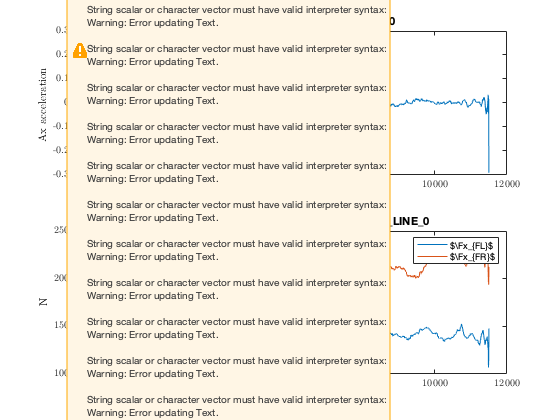

figure
subplot(2,1,1)
plot(smooth(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.axG,500),'DisplayName','$\axG$')
xlabel('time (s)');ylabel('Ax acceleration ');
title('Vehicle Acceleration-STRAIGHT_LINE_0');
%Longitudinal forces, straight line at constant velocity
subplot(2,1,2)
plot(smooth(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.Fx_FL,500),'DisplayName','$\Fx_{FL}$')
hold on
plot(smooth(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.Fx_FR,500),'DisplayName','$\Fx_{FR}$')
xlabel('time (s)');ylabel('N');
title('Front Wheels Longitudinal Forces-STRAIGHT_LINE_0');
legend

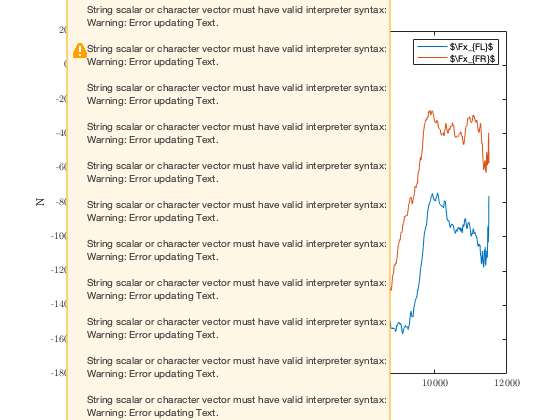



Cr_fl = mean(smooth(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.Fx_FL,500))/(mF * 9.81/2);
Cr_fr = mean(smooth(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.Fx_FR,500))/(mF * 9.81/2);

ft = fittype('Cr*x'); 
fit_Cr_FL = fit(mean(STRAIGHT_LINE_0.Fz_FL),mean(STRAIGHT_LINE_0.Fx_FL),ft,'StartPoint', 0);
fit_Cr_FR = fit(mean(STRAIGHT_LINE_0.Fz_FR),mean(STRAIGHT_LINE_0.Fx_FR),ft,'StartPoint', 0);
Cr_FL = fit_Cr_FL.Cr;
Cr_FR = fit_Cr_FR.Cr;

%Lateral forces, straight line at constant velocity
figure
plot(smooth(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.Fy_FL,Fs),'DisplayName','$\Fx_{FL}$')
hold on
plot(smooth(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.Fy_FR,Fs),'DisplayName','$\Fx_{FR}$')
xlabel('time (s)');ylabel('N');
title('Front Wheels Lateral Forces');
legend

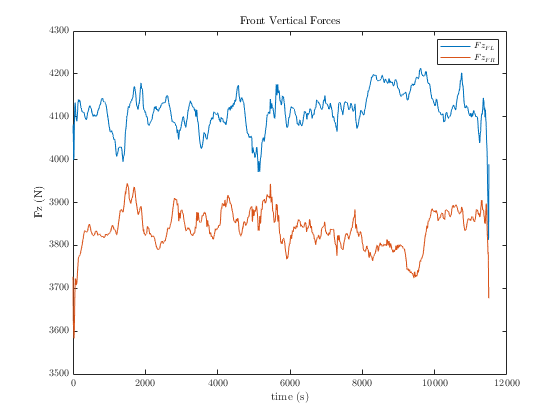


figure
plot(smooth(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.Fz_FL,500),'DisplayName','$Fz_{FL}$')
hold on
plot(smooth(STRAIGHT_LINE_0.time,STRAIGHT_LINE_0.Fz_FR,500),'DisplayName','$Fz_{FR}$')
xlabel('time (s)');ylabel('Fz (N)');
title('Front Vertical Forces');
legend

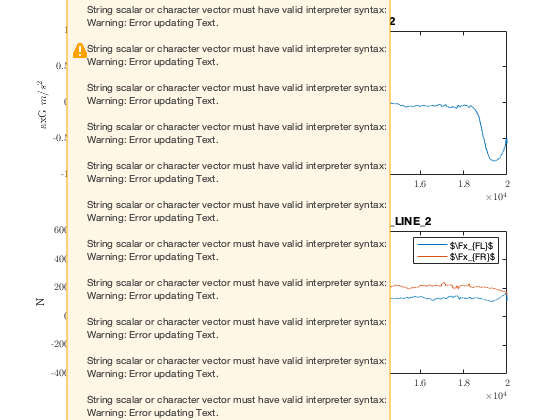


%Estimation using STRAIGHT_LINE_2
%Check acceleration
figure
subplot(2,1,1)
plot(smooth(STRAIGHT_LINE_2.time,STRAIGHT_LINE_2.axG,500),'DisplayName','$\axG$')
xlabel('time (s)');ylabel('axG $m/s^2$ ');
title('Vehicle Acceleration-STRAIGHT_LINE_2');
%Longitudinal forces, straight line at constant velocity
subplot(2,1,2)
plot(smooth(STRAIGHT_LINE_2.time,STRAIGHT_LINE_2.Fx_FL,500),'DisplayName','$\Fx_{FL}$')
hold on
plot(smooth(STRAIGHT_LINE_2.time,STRAIGHT_LINE_2.Fx_FR,500),'DisplayName','$\Fx_{FR}$')
xlabel('time (s)');ylabel('N');
title('Front Wheels Longitudinal Forces--STRAIGHT_LINE_2');
legend

%Cr_fl_2 = mean(smooth(STRAIGHT_LINE_2.time,STRAIGHT_LINE_2.Fx_FL,Fs))/(mF * 9.81/2);
%Cr_fr_2 = mean(smooth(STRAIGHT_LINE_2.time,STRAIGHT_LINE_2.Fx_FR,Fs))/(mF * 9.81/2);

ft = fittype('Cr*x'); 
fit_Cr_FL_2 = fit(mean(STRAIGHT_LINE_2.Fz_FL),mean(STRAIGHT_LINE_2.Fx_FL),ft,'StartPoint', 0);
fit_Cr_FR_2 = fit(mean(STRAIGHT_LINE_2.Fz_FR),mean(STRAIGHT_LINE_2.Fx_FR),ft,'StartPoint', 0);
Cr_FL_2= fit_Cr_FL_2.Cr;
Cr_FR_2 = fit_Cr_FR_2.Cr;


%TO DO
%Add theory: choices, live script